clear, clc, close all

Cprime = 1;  % uF
Rprime = 1;  % kOhms
R1prime = 1; % kOhms
R2prime = 2.111; % kOhms

C = (Cprime)*0.000001; % Converting positive feedback capacitance to Farads
R = (Rprime)*1000;     % Converting positive feedback resistance to Ohms
R1 = (R1prime)*1000;   % Converting forward gain resistance, R1, to Ohms
R2 = (R2prime)*1000;   % Converting forward gain resistance, R2, to Ohms

% Calculates and displays the oscillating frequencyok
wo = (1/(C*R));
disp(['Oscillating frequency for the system w0= ', num2str(wo)])

Oscillating frequency for the system w0= 1000



% Calculates and displays the open loop transfer function A*b = tf([(1+(R2/R1)) 0],[C*R 3 (1/(C*R))])
disp('Open loop gain A*b:')

Open loop gain A*b:


L = tf([(1+(R2/R1)) 0],[C*R 3 (1/(C*R))])


L =
 
         3.111 s
  ----------------------
  0.001 s^2 + 3 s + 1000
 
Continuous-time transfer function.



zpk(L) % Displays zero pole gain form of the loop gain transfer function, L


ans =
 
       3111 s
  ----------------
  (s+2618) (s+382)
 
Continuous-time zero/pole/gain model.




% Calculates and displeys the closed loop transfer function, Af
disp('Closed loop gain Af:')

Closed loop gain Af:


Af = (1 + R2/R1)/(1-L)


Af =
 
  0.003111 s^2 + 9.333 s + 3111
  -----------------------------
   0.001 s^2 - 0.111 s + 1000
 
Continuous-time transfer function.



zpk(Af) % Displays zero-pole-gain form of the closed loop transfer function, Af


ans =
 
  3.111 (s+2618) (s+382)
  ----------------------
   (s^2 - 111s + 1e06)
 
Continuous-time zero/pole/gain model.



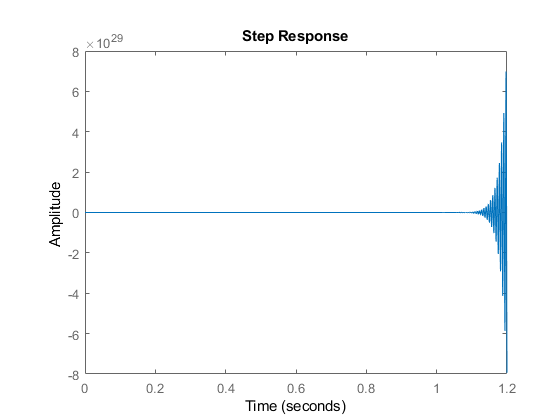


% Transient step response of the close loop transfer function Af
figure(11)
step(Af)

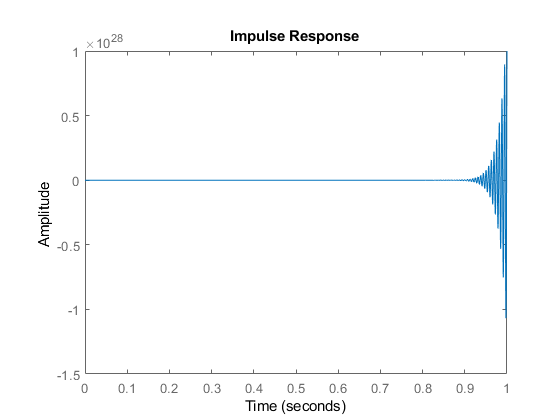




% Transient impulse response of the close loop transfer function Af
figure(2)
impulse(Af)